# 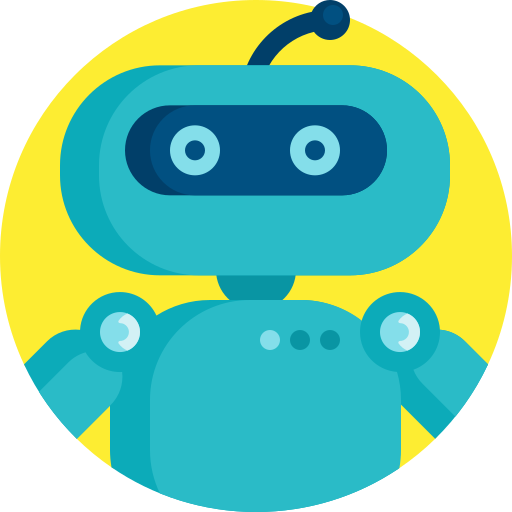

# **MEC4127F: Introduction to Robotics**

# Chapter 7: Trajectory generation

## 7.1 Introduction

Given a high-level objective, such as moving a robot from one defined point in 2D space to another, the task of defining the corresponding trajectory may seem trivial. A straight line that joins the two points will give the shortest path. However, the question still remains how quickly one must along the path (in terms of velocity and acceleration) in order to be energy efficient. Additionally, the particular robotic platform may not be capable of performing the simple straight line movement as a result of obstacles, workspace limitations, or kinematic constraints (imagine a car trying to parallel park). There may also be time requirements related to moving from the initial location to the final location. 

The first consideration should be whether the robot is physically capable of moving from the initial pose to the final pose. The underlying *path* that joins the two poses should exist within the robot workspace in order to avoid unrealistic expectations of the robot. A *trajectory* is a path on which a timing law is specified. If our path was described on a 2D plane, then the corresponding trajectory can be thought of as a 3D description of the 2D plane, where a time axis has been added. In this way, the path is parameterised by a time variable and this inherently induces derivative information from our original path (e.g. velocity and acceleration trajectories). We are no longer just interested in where the path is, but also *when* it is. When dealing with the trajectory generation problem, it is important to consider the dynamic and kinematic limitations of the robotic platform. A servomotor, for example, has a rated maximum slew rate (rate of change of position), which means that it cannot be used to reliably track trajectories that require angular velocities above its rated limit. Trajectories should therefore be generated with the underlying saturation limits of the actuators in mind. Violating said limits may not seem catastrophic for tame single-input-single-output systems, but larger multi-input-multi-output systems can experience an irrecoverable instability if saturation occurs at the wrong time. 

Before diving into the content, we will begin my defining the key lements that make up a trajectory.

### 7.1.1 Path

A generalised **path** $X(s)$ describes the mapping of a scalar path parameter, $s$, to a point in the robot's configuration space (the space that describes all positions the particular robot could take). Scalar parameter $s$ is assumed to start at $0$ at the start of the path, and equal $1$ at the end. As $s$ increases from $0$ to $1$, the robot moves along the specified path. As we will show later, $X(s)$ can refer to a rectilinear path, or a rotational path.

### 7.1.2 Time scaling

The focus of this Chapter will be to determine the appropriate **time scaling**, $s(t)$, which assigs a value $s$ to each time time point $t\in \left[0,T\right]$, where $T$ is the completion time of the manoeuvre. Therefore, the function $s(t)$ performs the following mapping:

$s~:~\left[0,T\right]\rightarrow \left[0,1\right]$.

For example, at the start of the path, $t=0$, which maps to $s(t)=0$, whereas at the end of the manoeuvre, $t=T$, and $s(t)=1$. The following sections will look at defining the mapping for all points in $t\in \left(0,T\right)$.

### 7.1.3 Trajectory

When a path and time scaling are combined, the result is defined as a **trajectory**, $X(s(t))$, or $X(t)$ in short. A trajectory therefore has spatial and temporal meaning. The robot is no longer just required to be in a particular configuration, but rather also be in that particular configuration at a specified time.

The velocity and acceleration along a trajectory can be defined, respectively, using chain rule as


$$\dot{X}=\frac{dX}{ds}\dot{s},$$



$$\ddot{X}=\frac{dX}{ds}\ddot{s}+\frac{d^2X}{dX^2}\dot{s}^2.$$


We require the robot's acceleration (and by extension, dynamics) to be well defined. As such, both $X(s)$ and $s(t)$ must be twice differentiable.

## 7.2 Straight-line paths

A **straight-line path** is the simplest form of joining a start configuration, $X_0$, and end configuration, $X_T$ — be it a straight line in translation or rotation (or both). 

For rectilinear motion and rotations about a single axis straight line equations can be written as


$$X(s)=X_0+s(X_T-X_0),$$


where $s\in \left[0,1\right]$. Notably,

- $s=0~\Rightarrow~X(s)=X_0$,

- 
$$s=1~\Rightarrow~X(s)=X_T.$$


The partial derivatives of $X(s)$ with respect to $s$ can be calculated as


$$\frac{dX}{ds}=X_T-X_0,$$


$\frac{d^2X}{ds^2}=0$.

The result above implies that a trajectory using straight line paths will have velocity and acceleration profiles of


$$\begin{array}{ll}
\dot{X}
&=\frac{dX}{ds}\dot{s},\\
&=\left(X_T-X_0\right)\dot{s},
\end{array}$$



$$\begin{array}{ll}
\ddot{X}
&=\frac{dX}{ds}\ddot{s}+\frac{d^2X}{dX^2}\dot{s}^2,\\
&=\frac{dX}{ds}\ddot{s},\\
&=\left(X_T-X_0\right)\ddot{s}.
\end{array}$$


### 7.2.1 Linear interpolation

When applied to translational paths, the equation $X(s)=X_0+s(X_T-X_0)$ is often also referred to as **linear interpolation** (LERP). This formulation can be used to construct an $n$-dimensional path for the translation (position) of a particular robot. For example, if a robot's desired position in $\{W\}$ is given by ${^W{\bf p}^*(s)\in\mathbb{R}^3$, LERP can construct an associated straight-line path of


$${^W{\bf p}^*}(s)={^W{\bf p}^*_0}+s\left({^W{\bf p}^*_T}-{^W{\bf p}^*_0}\right),$$


where ${^W{\bf p}^*_0}$ and ${^W{\bf p}^*_T}$ are the desired start and end positions of the robot in the 3D world frame, respectively.

### 7.2.2 Spherical linear interpolation

**Spherical linear interpolation **(SLERP) is the rotational counterpart to linear interpolation, which is required when multi-dimensional rotations are of interest. One can picture SLERP as a path that is drawn along a unit-radius great circle arc. The equation for LERP of $X(s)=X_0+s(X_T-X_0)$ cannot be applied in general to rotation motion, as shown in Chapter 3. We instead can make use of exponential coordinates when applying the time scaling $s$ and then convert back to rotation matrices or quaternions when performing the rotation.

#### 7.2.2.1 Rotation matrices

Recall that the rotation matrix $\bf R$ is related to exponential coordinates $\alpha \hat{\bf v}$ using the matrix exponential of


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf v} \rfloor\alpha}.$$


Exponential coordinates can also be extraced from rotation matrices (in skew-symmetic form) using the matrix logarithm:


$$ {\lfloor \hat{\bf v} \rfloor\alpha}=\log{\bf R}.$$


Considering an initial orientation of $^W{\bf R}(0)={^W{\bf R}_0}$ and final orientation of $^W{\bf R}(T)={^W{\bf R}_T}$, the incremental rotation matrix that rotates ${^W{\bf R}_0}$ to ${^W{\bf R}_T}$, given by ${^0{\bf R}_T}$, accomplishes


$${^W{\bf R}_T} = {^W{\bf R}_0}{^0{\bf R}_T}.$$


As the notation implies, ${^0{\bf R}_T}$ is rotation matrix describing the orientation of the reference frame at the end of the motion, with respect to the initial reference frame. One can then solve for ${^0{\bf R}_T}$ based on


$$\begin{array}{ll}
{^0{\bf R}_T} 
&= {^W{\bf R}_0^T}{^W{\bf R}_T},\\
&= {^0{\bf R}_W}{^W{\bf R}_T}.
\end{array}$$


Using the matrix logarithm, we can extract the exponential coordinates from ${^0{\bf R}_T}$ using


$$\begin{array}{ll}
 {\lfloor {^0\hat{\bf v} \rfloor\Delta\alpha}
&=\log{^0{\bf R}_T} ,\\
&= \log\left({^0{\bf R}_W}{^W{\bf R}_T}\right).
\end{array}$$


The time scaling parameter $s$ can be applied to the exponential form of the incremental rotation using


$$\begin{array}{ll}
 s{\lfloor {^0\hat{\bf v} \rfloor\Delta\alpha}
&=s\log{^0{\bf R}_T} ,\\
&= s\log\left({^0{\bf R}_W}{^W{\bf R}_T}\right).
\end{array}$$


A simple way to think of this time scaling is that the effective rotation angle of $s\Delta\alpha$ is interpolated based on the variation of $s\in \left[0,1\right]$.

Finally, the time-scaled exponential coordinates can be mapped back into rotation matrix form using the matrix exponential and then pre-multiplied by the rotation matrix describing the initial orientation, namely ${^W{\bf R}_0}$, to obtain the time-scaled parameterisation of the trajectory:


$$\begin{array}{ll}
{^W{\bf R}}(s)
&={^W{\bf R}_0}{\bf e}^{s\log{^0{\bf R}_T}},\\
&={^W{\bf R}_0}{\bf e}^{s\log\left({^0{\bf R}_W}{^W{\bf R}_T}\right)}.
\end{array}$$


#### Example: SLERP using rotation matrices

preamble...

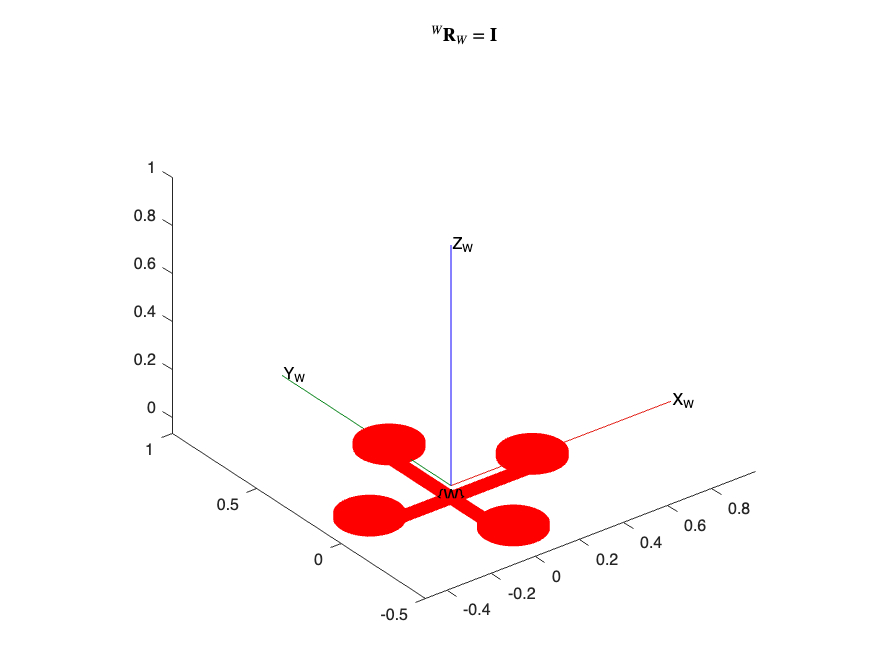

R0 = [ -0.666666666666667   0.133333333333333   0.733333333333334;
        0.666666666666667  -0.333333333333333   0.666666666666667;
        0.333333333333333   0.933333333333334   0.133333333333333];
RT = [1 0 0;
      0 1 0;
      0 0 1];
dR = R0'*RT;

T = 2;
numSamples = 1e2;
t = linspace(0,T,numSamples);
s = t/T;

alphaV = zeros(length(t),3);

figure
for i=1:length(t)
    R = R0*expm(s(i)*logm(dR));

    axang = rotm2axang(R);    %extract current axis-angle elements for sake of plotting
    alphaV(i,:) = axang(4)*axang(1:3);    %consolidate axis-angle form into exponential coordinates for plotting

    %3D visualisation of rotational motion
    plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
    axis equal, title('$^W{\bf R}_W={\bf I}$',Interpreter='latex')
    pause(1/numSamples)

end

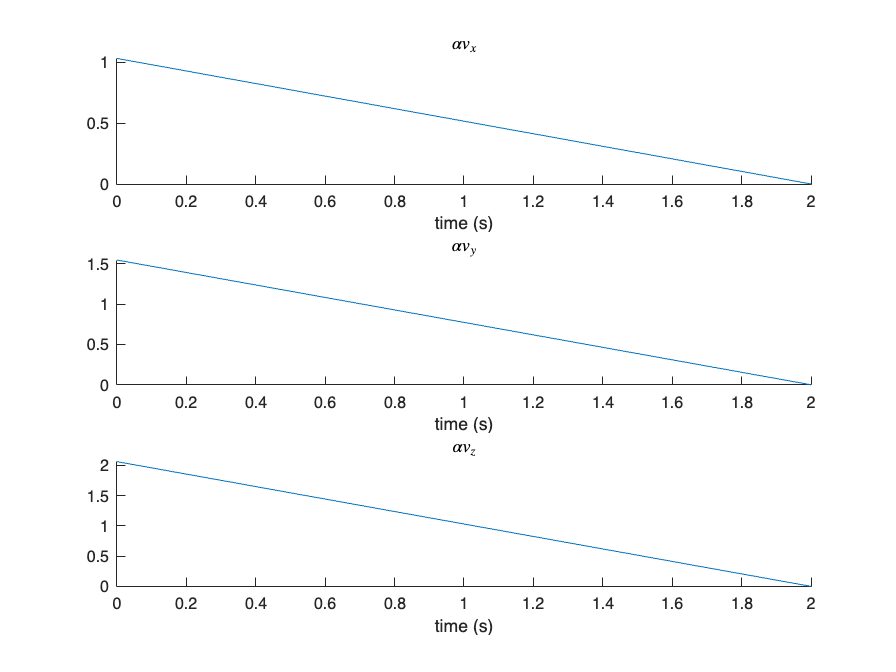

%plot exponential coordinates as a function of time
figure
subplot(3,1,1),hold on
plot(t,alphaV(:,1)),title('$\alpha v_x$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,2),hold on
plot(t,alphaV(:,2)),title('$\alpha v_y$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,3),hold on
plot(t,alphaV(:,3)),title('$\alpha v_z$',Interpreter='latex'),xlabel('time (s)')

#### 7.2.2.2 Quaternions

The quaternion formulation using SLERP follows a similar procedure to that of the rotation matrix. We first define the *exponential mapping*, $\text{exp}$, that relates the exponential coordinates to quaternions, as


$$\text{exp:} \qquad \alpha\hat{\bf v}\in \mathbb{R}^3 \rightarrow {\bf q}\in \mathbb{R}^4.$$


We can therefore use this mapping to easily represent the quaternion as


$$\begin{array}{ll}
{\bf q}
&=\text{exp}\left({\alpha\hat{\bf v}}\right)
= \left[\begin{array}{cc}    \cos\frac{\alpha}{2} \\    \sin\frac{\alpha}{2}\hat{\bf v}    \\ \end{array}\right].
\end{array}$$


The inverse is referred to as the *logarithmic mapping* with the associated property of 


$$\text{log:} \qquad {\bf q}\in \mathbb{R}^4 \rightarrow \alpha\hat{\bf v}\in \mathbb{R}^3,$$


or explicitly,


$$\begin{array}{ll}
\alpha\hat{\bf v}=
\text{log}\left({\bf q}\right).
\end{array}$$


Considering an initial orientation of $^W{\bf q}_0$ and final orientation of $^W{\bf q}_T$, the incremental rotation matrix that rotates $^W{\bf q}_0$ to $^W{\bf q}_T$, given by ${^0{\bf q}_T}$, accomplishes


$${^W{\bf q}_T = {^W{\bf q}_0}\otimes{^{0}{\bf q}_{T}.$$


As the notation implies, ${^0{\bf q}_T}$ is the quaternion describing the orientation of the reference frame at the end of the motion, with respect to the initial reference frame. One can then solve for ${^0{\bf q}_T}$ based on


$$\begin{array}{ll}
{^0{\bf q}_T} 
&= {^W{\bf q}_0^{-1}}\otimes{^W{\bf q}_T},\\
&= {^0{\bf q}_W}\otimes{^W{\bf q}_T}.
\end{array}$$


Using the logarithmic mapping, we can extract the exponential coordinates from ${^0{\bf q}_T}$ using


$$\begin{array}{ll}
\alpha {^0\hat{\bf v} }
&=\log\left({^0{\bf q}_T} \right),\\
&= \log\left({^0{\bf q}_W}\otimes{^W{\bf q}_T}\right).
\end{array}$$


The time scaling parameter $s$ can then be applied to the exponential form of the incremental rotation using


$$\begin{array}{ll}
 s \alpha {^0\hat{\bf v}
&=s\log{^0{\bf q}_T} ,\\
&= s\log\left({^0{\bf q}_W}\otimes{^W{\bf q}_T}\right).
\end{array}$$


A simple way to think of this time scaling is that the effective rotation angle of $s\alpha$ is interpolated based on the variation of $s\in \left[0,1\right]$.

Finally, the time-scaled exponential coordinates can be mapped back into quaternion form using the exponential mapping and then pre-multiplied by the rotation matrix describing the initial orientation, namely ${^W{\bf q}_0}$, to obtain the time-scaled parameterisation of the trajectory:


$$\begin{array}{ll}
{^W{\bf q}}(s)
&={^W{\bf q}_0}\otimes\text{exp}\left({s\log{^0{\bf q}_T}}\right),\\
&={^W{\bf q}_0}\otimes\text{exp}\left({s\log\left({^0{\bf q}_W}\otimes{^W{\bf q}_T}\right)}\right).
\end{array}$$


## 7.3 Time-scaling

This section will consider two approaches to time scaling, namely:

- polynomial interpolation (1st-order, 3rd-order, 5th-order);

- trapezoidal velocity profiles.

We will show that as the degree of the polynomial interpolation becomes higher, we obtain smoother, more well-behaved trajectories. However, we also need to specify more information about the trajectory, which may not be easily known. Trapezoidal velocity profiles are an alternative approach to polynomial interpolation that considers time optimality over smoothness, which also comes with some strict constraints.

We will only consider point to point motion in this Section. That is, a motion that starts at rest and ends at rest. A latter section on polynomial splines will cover the general motion case, where the initial and final velocities are not necessarily zero.

### 7.3.1 First-order polynomial interpolation

Consider the task of using a first-order time scaling to describe the trajectory that adheres to $s~:~\left[0,T\right]\rightarrow \left[0,1\right]$. The corresponding $1^{st}$-order position trajectory can be written as 


$$\begin{array}{cc}s(t) = a_0+a_1t, \end{array}$$


where $\{a_0,a_1\}\in\mathbb{R}$ are constants, $t$ is the time parameter, and $T$ is the time that corresponds with the end of the trajectory. Assuming $t \in [0,T]$ , we can find both parameters using


$$\begin{array}{cc}    s(0) = a_0=0,\\ \end{array}$$



$$\begin{array}{cc}    s(T) = a_0+a_1T = a_1T=1.\\ \end{array}$$


We can therefore determine $a_i$ as


$$\begin{array}{cc}
\left[\begin{array}{cc}    a_0 \\    a_1    \\ \end{array}\right] = \left[\begin{array}{cc}    0 \\    \frac{1}{T}    \\ \end{array}\right], \end{array}$$


which results in the simple first-order time-scaling of 


$$\begin{array}{cc}s(t) = \frac{t}{T}. \end{array}$$


Note that only the terminal time needs to be specified to define $s(t)$. To see how the corresponding velocity trajectory will evolve, we differentiate $s(t)$, which gives us


$$\begin{array}{cc}\dot{s}(t) = \frac{1}{T}.&  \end{array}$$


A demonstration of first-order time scaling can be seen in the Example in Section 7.2.2.1.

The choice of first-order polynomial means that we have no way to specify a desired initial and final time-scaling velocity. Given the task of point to point motion, which implies that the robot is stationery (zero velocity) at the start and end of the motion, the velocity will be required to instantaneously jump from zero to $\frac{1}{T}$ at $t=0$ , and from $\frac{1}{T}$ back to zero at $t=T$ (see Figure 7.1). 

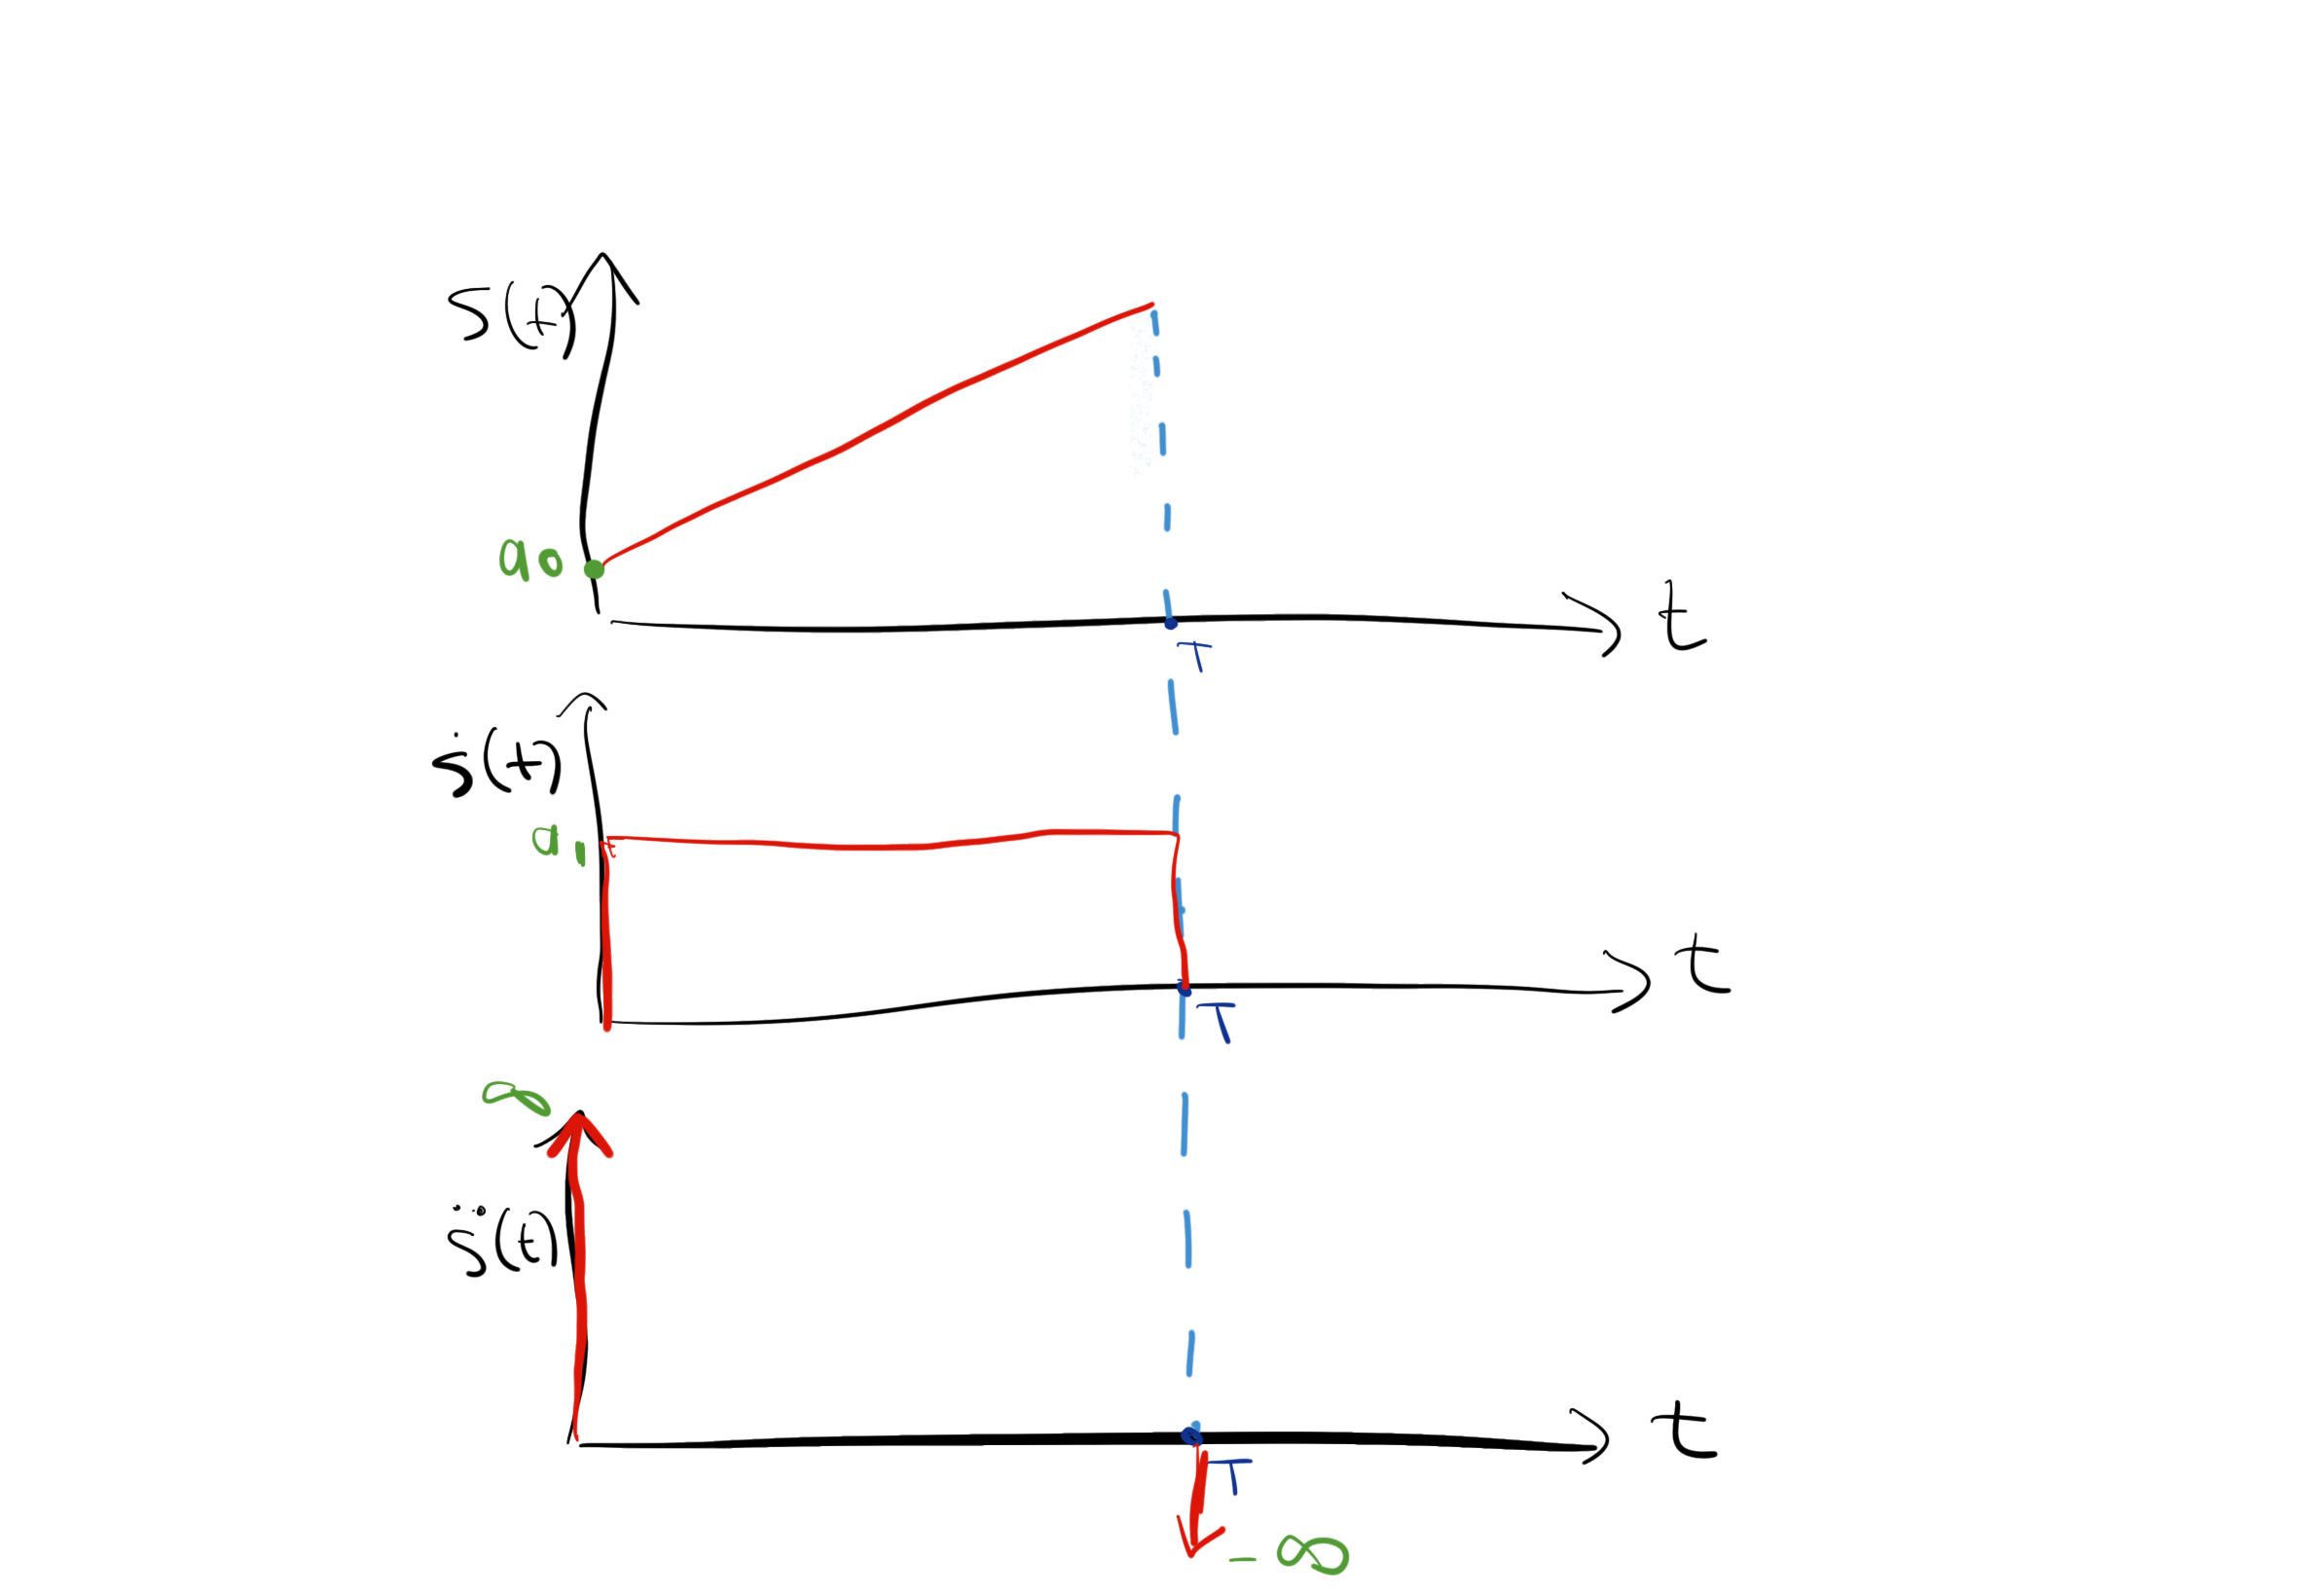

**Figure 7.1:** Linear interpolation of a point to point trajectory and the resulting time-derivative profiles.
 

This implies that the corresponding time-scaling acceleration at $t=0$ and $t=T$ are infinite impulses (dirac delta functions) as the velocity gradient at these time points are infinitely steep. This type of impulsive behaviour implies instantaneously applying a very large amount of energy in practice and should be avoided ideally, as the actuators that are inherently responsible for motion cannot produce such a signal, nor do they want to! - sharp signals on actuators results in wear and can damage the mechanical components. For this reason, a higher order interpolation method is required that has some favourable derivative properties.

### 7.3.2 Cubic polynomial interpolation

Cubic ($3^{rd}$-order) polynomials are commonly used to interpolate between two points, and can be written as 


$$\begin{array}{cc}s(t) = a_0+a_1t+a_2t^2+a_3t^3, \end{array}$$


where $\{a_0,a_1,a_2,a_3\}\in\mathbb{R}$ are constants. The equation above can be repeatedly differentiated to find the corresponding kinematic profiles, namely, the quadratic *velocity* profile 


$$\begin{array}{cc}\dot{s}(t) = a_1+2a_2t+3a_3t^2, \end{array}$$


the linear *acceleration* profile 


$$\begin{array}{cc}\ddot{s}(t) = 2a_2+6a_3t, \end{array}$$


and the constant *jerk* profile 


$$\begin{array}{cc}\dddot{s}(t) = 6a_3. \end{array}$$


With reference to Figure X as an example, the velocity profile notably exhibits a continuous behaviour, as a result of being twice differentiable, which is a necessary condition for a *smooth* position trajectory. However, the acceleration and jerk profiles do not have the same continuous property. 

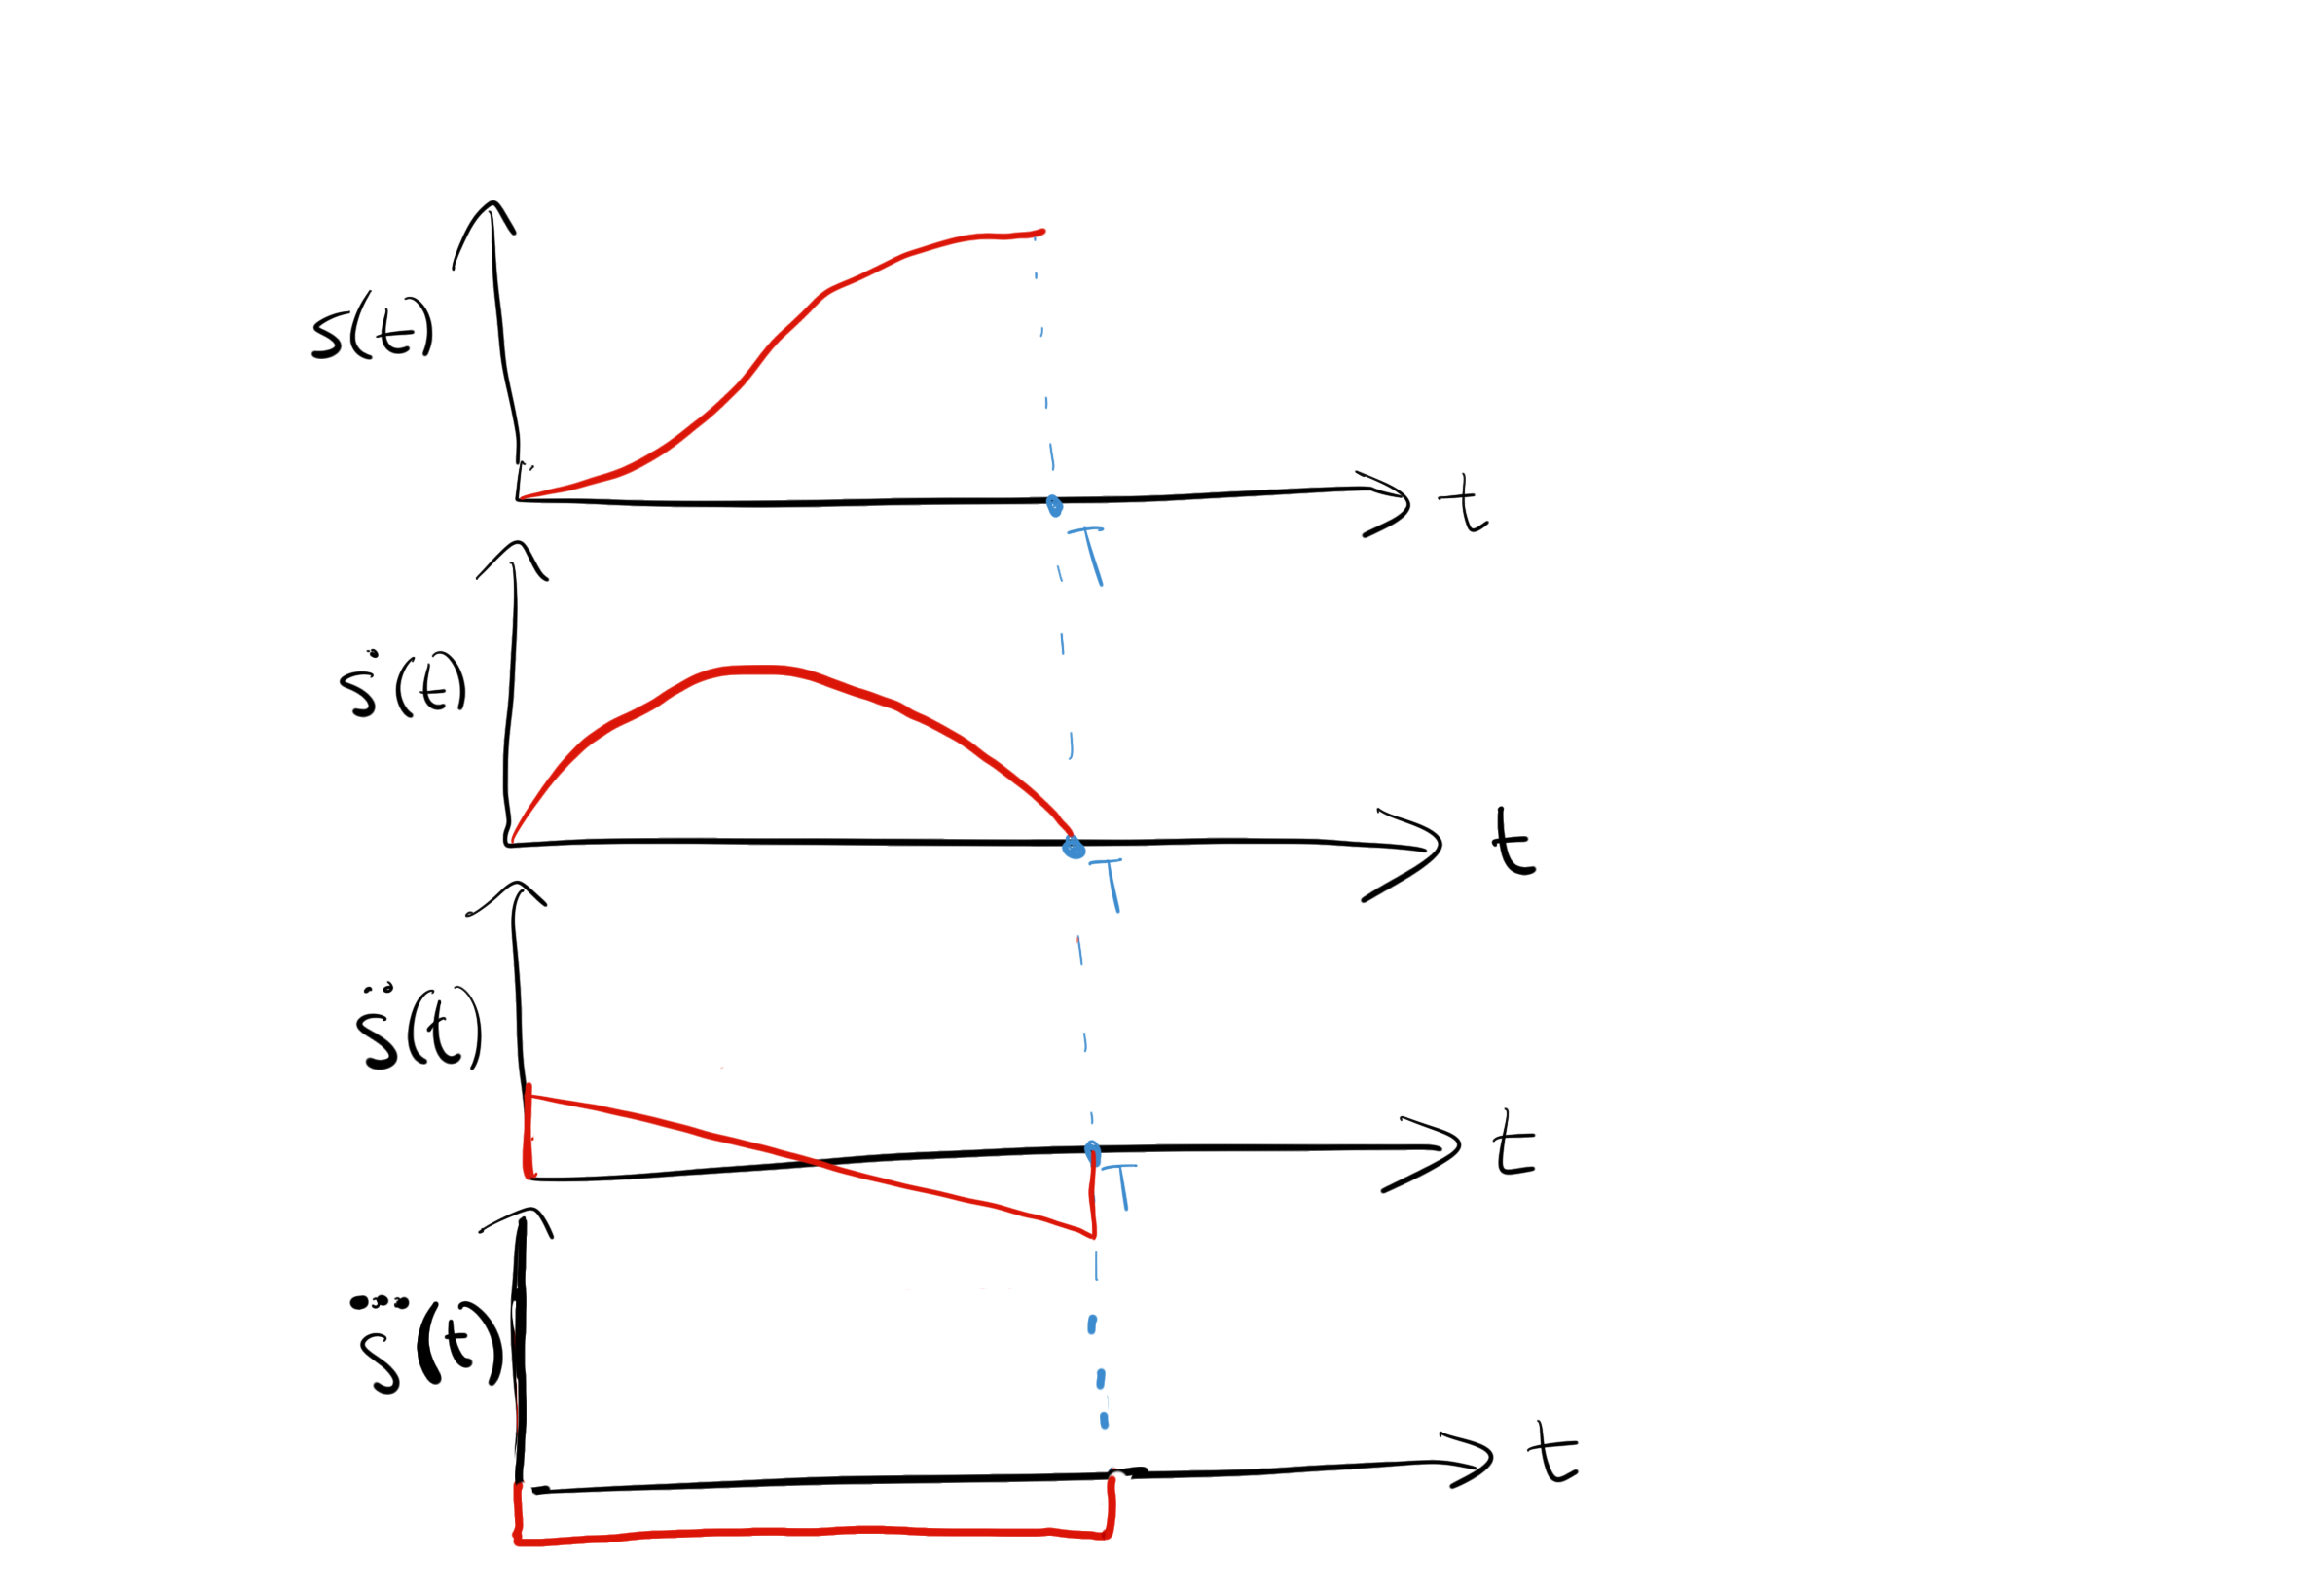

**Figure 2:** Cubic polynomial interpolation of a point to point trajectory and the resulting time-derivative profiles.
 

If we were interested in ensuring there was continuity at the acceleration and jerk level, we could use a higher order polynomial, such a quartic ( $4^{th}$-order) or quintic ( $5^{th}$-order), which will be discussed in a latter section.

#### **Definition:** Smooth trajectory

A trajectory in which the first two temporal derivatives are continuous is classed as being a **smooth trajectory**. 

Smoothness is appealing if we want our robot to operate in an energy efficient and controlled manner. In fact, the cubic polynomial trajectory originates as a result of solving an energy-optimal cost function. So while we may not have a truly smooth trajectory at all kinematic levels, we are at least commanding finite acceleration commands; something that an actuator can more closely approximate. 

Given that there are four undefined constants of $\{a_0,a_1,a_2,a_3\}$, we need to impose four constraints on the various profiles in order to solve said parameters. This can be done by assigning initial and final position and velocity requirements. Based on the requirement of the time-scaling function, we require $s(0)=0$ and $s(T)=1$. We would then have to choose corresponding initial and final velocity constraints of $\dot{s}(0)$ and $\dot{s}(T)$. In the case of point to point motion (with the robot required to be stationary at the start and end of the motion), this is simply $\dot{s}(0)=\dot{s}(T)=1$. Based on this information, we can make the following deductions:


$$\begin{array}{cc}s(0) = a_0=0 \end{array}.$$



$$\begin{array}{ll}\dot{s}(0) 
= a_1+2a_20+3a_30^2=a_1=0.
\end{array}$$



$$\begin{array}{ll}    
s(T)
&=a_0+a_1T+a_2T^2+a_3T^3,\\
&=a_1T+a_2T^2+a_3T^3 ,\\
&=a_2T^2+a_3T^3 ,\\
&= 1.\\ \end{array}$$



$$\begin{array}{ll}    
\dot{s}(T) 
=a_1+2a_2T+3a_3T^2=2a_2T+3a_3T^2=0.
\end{array}$$


The last two equations above constitute two unknown parameters — $\{a_2,a_3\}$. We can also write this in matrix form as


$$\begin{array}{cc}\left[\begin{array}{cccccccccccccc}    T^2 & T^3   \\  2T & 3T^2 \end{array}\right]    \left[\begin{array}{cc}    a_2 \\ a_3    \\ \end{array}\right] =     \left[\begin{array}{cc}    1 \\ 0    \\ \end{array}\right],\end{array}$$


and then invert our matrix to solve for our constant vector


$$\begin{array}{ll}\left[\begin{array}{cc}    a_2 \\ a_3    \\ \end{array}\right] 
&=     \left[\begin{array}{cccccccccccccc}    T^2 & T^3   \\  2T & 3T^2    \\ \end{array}\right]^{-1}    \left[\begin{array}{cc}    1 \\ 0    \\ \end{array}\right],\\
&=\left[\begin{array}{cc}    \frac{3}{T^2}\\ -\frac{2}{T^3}    \\ \end{array}\right] .
\end{array}

$$


Note that in point to point motion  we only need to select terminal time $T$ to determine $\{a_2,a_3\}$.

syms T real

M = [T^2 T^3;
     2*T 3*T^2];
A = M\[1 0]'

$$A = \left(\begin{array}{c} \frac{3}{T^{2}}\\ -\frac{2}{T^{3}} \end{array}\right)$$


-A(1)/(3*A(2))

$$ans = \frac{T}{2}$$

Once our constants and initial conditions are defined, we can populate the kinematic equations governing the time-scaling function, namely 


$$\begin{array}{ll}
s(t) 
= a_0+a_1t+a_2t^2+a_3t^3 = \frac{3}{T^2}t^2-\frac{2}{T^3}t^3, 
\end{array}$$



$$\begin{array}{cc}\dot{s}(t) = a_1+2a_2t+3a_3t^2= \frac{6}{T^2}t-\frac{6}{T^3}t^2, \end{array}$$



$$\begin{array}{cc}\ddot{s}(t) = 2a_2+6a_3t=\frac{6}{T^2}-\frac{12}{T^3}t, \end{array}$$



$$\begin{array}{cc}\dddot{s}(t) = 6a_3=-\frac{12}{T^3}. \end{array}$$


Notably, we have no control over how the acceleration profile evolves. If we wanted to have a say about the initial and final acceleration conditions, we would require a quintic polynomial — see Section 7.3.3. Given that our velocity profile from the equation above is quadratic, we can find the time point when the maximum value occurs (at the turning point) as


$$\begin{array}{cc}t_{max} = -\frac{a_2}{3a_3}=\frac{T}{2},\end{array}$$


which occurs at the halfway point of the motion due to symmetry. The corresponding maximum velocity then follows as


$$\begin{array}{cc}\dot{s}_{max}=\dot{s}(t_{max}) = \frac{6}{T^2}t_{max}-\frac{6}{T^3}t_{max}^2=\frac{3}{2T}.\end{array}$$


syms T real
t_max = T/2

$$t\_max = \frac{T}{2}$$

ds_max = 6/T^2*t_max-6/T^3*t_max^2

$$ds\_max = \frac{3}{2\,T}$$

If we know the time-scaling velocity limit, $\dot{s}_{lim}$, we can impose a constraint on the obtainable maximum velocity, and then ensure that


$$\dot{s}_{max}=\frac{3}{2T}\leq \dot{s}_{lim}.$$
 

Recalling that the velocity of a straight-line trajectory is given as


$$\begin{array}{ll}
\dot{X}
&=\left(X_T-X_0\right)\dot{s},
\end{array}$$


we can quantify the maximum velocity of the trajectory, $\dot{X}_{max}>0$ based on


$$\begin{array}{ll}
\dot{X}_{max}
&=\left|X_T-X_0\right|\dot{s}_{max}\leq
\left|X_T-X_0\right|\dot{s}_{lim},
\end{array}$$


The time-scaling velocity limit can then be determined as


$$\begin{array}{ll}
\dot{s}_{lim}
=\frac{\dot{X}_{max}}{
\left|X_T-X_0\right|},
\end{array}$$


which can be used to enforce the selection of $T$ using


$$\dot{s}_{max}=\frac{3}{2T}\leq \frac{\dot{X}_{max}}{
\left|X_T-X_0\right|},$$


or explicitly

 
$$T \geq\frac{3
\left|X_T-X_0\right|}{2\dot{X}_{max}} .$$


We can similarly impose a constraint on our maximum obtainable acceleration. This is done by first identifying that the time-scaling acceleration profile will have a maximum value at either the start point or end point, as the acceleration profile is a straight line. In the case of point to point motion, the initial and final accelerations will be equivalent, resulting in the same constraint of


$$\frac{6}{T^2} \leq \ddot{s}_{lim},$$


where $\ddot{s}_{lim}$ is the time-scaling acceleration limit. Given that


$$\begin{array}{ll}
\ddot{X}
=\left(X_T-X_0\right)\ddot{s},
\end{array}$$


the maximum acceleration of the motion will be


$$\begin{array}{ll}
\ddot{X}_{max}
=\left|X_T-X_0\right|\ddot{s}_{max}\leq\left|X_T-X_0\right|\ddot{s}_{lim}.
\end{array}$$


We can therefore related the terminal time requirement to the maximum acceleration of the trajectory as


$$\begin{array}{ll}
\ddot{X}_{max}
\leq\frac{6\left|X_T-X_0\right|}{T^2},
\end{array}$$


or directly as

...

#### Example: Cubic polynomial trajectory

...

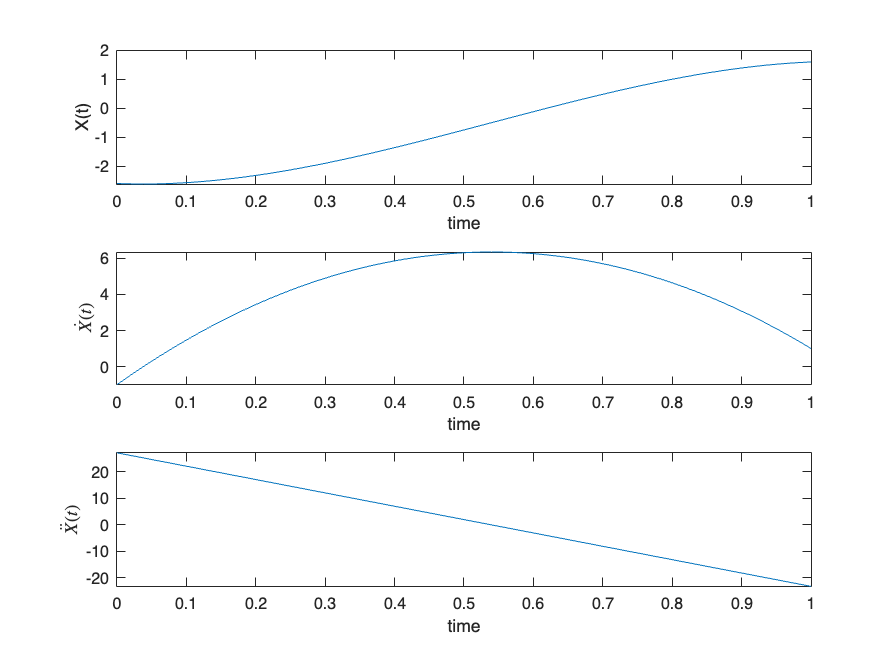

X0 =-2.6; %initial position
XT =1.6; %final position
dX0 =-1; %initial velocity
dXT =1; %terminal velocity

ds0 = dX0/(XT-X0);    %initial time-scaling velocity
dsT = dXT/(XT-X0);    %final time-scaling velocity

T = 1;    %completion time

M = [1 0 0 0;
     0 1 0 0;
     1 T T^2 T^3;
     0 1 2*T 3*T^2];

A = M\[0 ds0 1 dsT]';

t = linspace(0,T,1e3);

s = A(1)+A(2)*t+A(3)*t.^2+A(4)*t.^3;
ds = A(2)+2*A(3)*t+3*A(4)*t.^2;
dds = 2*A(3)+6*A(4)*t;

X = X0+s*(XT-X0);
dX = ds*(XT-X0);
ddX = dds*(XT-X0);

figure
subplot(3,1,1),plot(t,X),ylabel('X(t)'),xlabel('time')
subplot(3,1,2),plot(t,dX),ylabel('$\dot{X}(t)$',Interpreter='latex'),xlabel('time')
subplot(3,1,3),plot(t,ddX),ylabel('$\ddot{X}(t)$',Interpreter='latex'),xlabel('time')

### 7.3.3 Quintic polynomial interpolation

...skip?

### 7.3.4 Trapezoidal velocity profiles

While the polynomial trajectories are appealing from an energy efficient point of view at sufficiently high degree, they are not time-optimal. This is exemplified by the fact that any imposed velocity constraint can at best only momentarily be met at equality momentarily (at the turning point). This means that for almost the entire trajectory, the robot is not being driven at its velocity limit. Similarly, the acceleration will only be maximised at either the start point or end point of the trajectory (or both simultaneously), implying that the acceleration is below its theoretical maximum for every other point on the trajectory. This obviously means that we are not dealing with the time-optimal trajectory given the robot's dynamic constraints. 

A **trapezoidal velocity profile** is an alternative approach that blends different polynomial types together during a point to point manoeuvre — where the initial and final velocities are zero. The name originates from the fact that the velocity profile has a trapezoidal shape. With reference to Figure 4, the trajectory is split up into three phases:

- **Phase 1 **(*spool up*): Constant acceleration of $\ddot{s}=a$ for duration $t_a$.

- **Phase 2 **(*cruise*): Constant velocity of $\dot{s}=v$ for duration $t_v=T-2T_a$.

- **Phase 3 **(*spool down*): Constant deceleration of $\ddot{s}=-a$ for duration $t_a$.

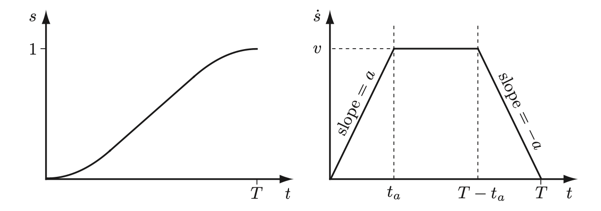

**Figure 4:** Characterization of a timing law with trapezoidal velocity profile in terms of position, velocity and acceleration \cite{cubic}.
 

The resulting position trajectory is made up of a linear segment (as a result of Phase 2) that is connected on either side by quadratic segments (as a result of Phase 1 and 3). As indicated in Figure 4, both the initial and final velocities are required to be zero, with the time durations of Phase 1 and Phase 3 also equal. 

To ensure the transition from $s_0$ to $s_T$ in the timespan of $T$ , the trajectory needs to satisfy certain constraints. The first constraint must enforce that the velocity achieved at the end of Phase 1 be equal to that of Phase 2: 


$$\begin{array}{cc}\ddot{s}_{max}t_c = \dot{s}_{max}(t_c)=\frac{s_m-s_c}{t_m-t_c},& \qquad (22)\\ \end{array}$$


where $s_c$ is the position value on the trajectory at the point where Phase 1 and Phase 2 meet (the end of the parabolic segment at $t_c$ ), and $s_m = \frac{s_0+s_T}{2}$ . Double integrating the acceleration profile during Phase 1, $s_c$ can be expressed as 


$$\begin{array}{cc}s_c = s_0+\frac{1}{2}\ddot{s}_{max}t_c^2.& \qquad (23)\\ \end{array}$$


Combining \eqref{eq: velocity constraint - TVP} and \eqref{eq: s_c = - TVP} results in 


$$\begin{array}{cc}\ddot{s}_{max} t_c^2 - \ddot{s}_{max} T t_c + s_T-s_0 = 0.& \qquad (24)\\ \end{array}$$


The Phase 1 time duration can then be found by solving the quadratic equation in \eqref{eq: quadratic eq. - TVP} 


$$\begin{array}{cc}t_c = \frac{T}{2}-\frac{1}{2}\sqrt{\frac{T^2\ddot{s}_{max}-4(s_T-s_0)}{\ddot{s}_{max}}},& \qquad (25)\\ \end{array}$$


where $t_c \leq T/2$ is required to facilitate the symmetric profile. Note that based on the structure of \eqref{eq: t_c = ... - TVP}, this will always be the case. If $\ddot{s}_{max}$ is additionally constrained such that sgn $(\ddot{s}_{max})=$ sgn $(s_T-s_0)$ , then a real-valued $t_c$ can be determined if 


$$\begin{array}{cc}|\ddot{s}_{max}| \geq \frac{4|s_T-s_0|}{T^2}.& \qquad (26)\\ \end{array}$$


If \eqref{eq: constraint on dds_max - TVP} is satisfied at equality, the resulting trajectory will not feature a cruise stage. More specifically, there will be a single time value, $t_c=T/2$ , that corresponds to the aforementioned velocity constraint, and this results in the trajectory only having a *spool up* stage and a *spool down* stage. Visually, this is shown as a triangular profile. On the other hand, if \eqref{eq: constraint on dds_max - TVP} is satisfied in some arbitrary sense, then two solutions for $t_c$ will exist, which will define the start and end points of the Phase 2 - the *cruise* stage. If we specify $s_0$ , $s_T$ , and $T$ , and by extension, $\dot{s}_{max}$ , the constraint in \eqref{eq: constraint on dds_max - TVP} can be used to limit the acceleration command based on the physical limitation of the platform. In other words, selecting a valid $\ddot{s}_{max}$ can then be used to populate \eqref{eq: t_c = ... - TVP}. The resulting piece-wise position trajectory follows as 


$$\begin{array}{cc}s(t) =     \left\{        \begin{array}{ll}            s_0+\frac{1}{2}\ddot{s}_{max}t^2 & 0\leq t\leq t_c \\            s_0+\ddot{s}_{max}t_c(t-t_c/2) & t_c < t\leq T-t_c \\            s_T-\frac{1}{2}\ddot{s}_{max}(T-t)^2 & T-t_c\leq t\leq T \\        \end{array}    \right..& \qquad (27)\\ \end{array}$$


We can therefore define a trajectory that demands the maximum actuator acceleration. We can similarly repose the setup of the problem to focus on the maximum velocity. Taking into account that $\dot{s}_{max}=\ddot{s}_{max} t_c$ , \eqref{eq: quadratic eq. - TVP} can be reposed as 


$$\begin{array}{cc}\dot{s}_{max} t_c - \dot{s}_{max} T  + s_T-s_0 = 0.& \qquad (28)\\ \end{array}$$


As in the case of \eqref{eq: t_c = ... - TVP}, we solve for $t_c$ , which gives us 


$$\begin{array}{cc}t_c = \frac{s_0-s_T+\dot{s}_{max}T}{\dot{s}_{max}}.& \qquad (29)\\ \end{array}$$


The constraint that ensures $t_c$ is a positive-real follows as 


$$\begin{array}{cc}\frac{s_T-s_0}{T}  \leq \dot{s}_{max}.& \qquad (30)\\ \end{array}$$


We additionally require $t_c \leq T/2$ , for sake of symmetry, which leads us to the other constraint of


$$\begin{array}{cc}\frac{s_0-s_T+\dot{s}_{max}T}{\dot{s}_{max}} \leq \frac{T}{2},& \qquad (31)\\ \end{array}$$


or more concisely. 


$$\begin{array}{cc}\dot{s}_{max} \leq 2\frac{s_T-s_0}{T}  .& \qquad (32)\\ \end{array}$$


Collating the results from \eqref{eq: s_max LB - TVP} and \eqref{eq: s_max UB - TVP}, the constraint on $\dot{s}_{max}$ can be written as 


$$\begin{array}{cc}\frac{s_T-s_0}{T}  \leq \dot{s}_{max} \leq 2\frac{s_T-s_0}{T}  .& \qquad (33)\\ \end{array}$$


As in the case of the acceleration limit, we can select a valid $\dot{s}_{max}$ using \eqref{eq: s_max LB+UB - TVP}, which will then inform the selection of $t_c$ in \eqref{eq: t_c VL - TVP}. Lastly, we can calculate the corresponding maximum acceleration from \eqref{eq: quadratic eq. 2 - TVP} as


$$\begin{array}{cc}\ddot{s}_{max} = \frac{s_0-s_T+\dot{s}_{max}T}{t_c^2},& \qquad (34)\\ \end{array}$$


which can then be used to populate our piece-wise position trajectory in \eqref{eq: position traj. - TVP}. In summary, depending on the particular constraint, be it velocity or acceleration, this limit can be directly imposed on the trajectory, and this will allow the system to theoretically be driven at its maximum capability for as long as possible (within the kinematically feasible task space). If required, we can also blend multiple trapezoidal velocity profiles together if there are more than two spatial points of interest to reach. The only catch is that the velocity profiles requires that the start and end velocity be set to zero. So, while we can define a trajectory that is made up of multiple trapezoidal velocity profiles, the resulting motion will take the form of starting from rest, accelerating, reaching constant velocity (if there is a cruise stage), decelerating, stopping, and then again accelerating as the subsequent profile begins. This stop-start sequence is not time-optimal, but is suitable for many robotics vehicles\footnote{Autonomous floor cleaning robots commonly use this type of method when generating feasible trajectories.}.

## 7.4 Polynomial splines

Polynomial splines, such as a cubic spline, is a method to find a smooth trajectory from a set of trajectory via points. Conceptually, if we were given a start point, and end point, and some finite amount of intermediate via points, then we can use polynomial interpolation between each set of adjacent points. These piece-wise polynomials are then blended together to form a single trajectory that is made of a set of polynomials. The result is a continuous trajectory that moves through each specified point.

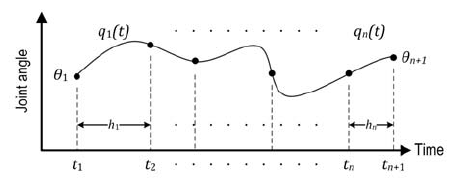

**Figure 3:** An example of a cubic spline trajectory with four via points.
 

In order to ensure that the full trajectory (from the start point to the end point) has some level of smoothness, we need to constrain the velocity such that it remains continuous at each via point (also known as *knots*). The trajectory generation problem would then require a sufficient amount of waypoint information, such as the required position and velocity at each waypoint, in order to construct a problem that is solvable. This type of trajectory generation method is useful in applications that require surveying or task-specific motion. For example, if a quadrotor is required to inspect different specific location on a map, we are not too concerned with how it behaves between these specificed locations (our waypoints), aside from the quadrotor to be energy efficient. So we can define a polynomial spline that intersects all the waypoints with a piece-wise set of polynomials. We start by considering a generalised trajectory with $N$ waypoints, and a start time and end time of $T_1=0$ and $T_N=T$ , respectively. $T_1$ then corresponds to the starting point, whereas $T_2$ is the time requirement at the second point. The polynomial is individually assessed between each moving pair of via points. For example, we will define a polynomial between point 1 and point 2, followed by a different polynomial that joins point 2 and point 3, and so on. At each point $i\in \{1,...N\}$ , the user specifies both the desired position, $s(T_i)$ and velocity, $\dot{s}(T_i)$ . The $N$ waypoints results in $N-1$ polynomials to be determined, with a segment duration equal to $\Delta T_j=T_{j+1}-T_j$ , where $j\in \{1,...N-1\}$ . In the case of cubic polynomials, four parameters need to be determined in order to fully specify a segment trajectory, as seen in \eqref{eq: s - CPI}. This means that a path with $N$ points will require $4(N-1)$ parameters to be determined in order to find all segment polynomials. However, as with Section \ref{sec: cubic polynomials}, we can solve for each segment as long as we adhere to the via point position and velocity constraints of 


$$\begin{array}{cccccc}\begin{split}    s(T_j) &= s_j, & \qquad (11)\\    s(T_j+\Delta T_j) &= s_{j+1},& \qquad (12)\\    \dot{s}(T_j) &= \dot{s}_j,& \qquad (13)\\    \dot{s}(T_j+\Delta T_j) &= \dot{s}_{j+1},& \qquad (14)\\\end{split}& \qquad (15)\\ \end{array}$$


where $s_j$ and $\dot{s}_j$ are the user specified position and velocity requirements at point $j$ . In other words, the end position and velocity of polynomial $j$ is required to match the starting position and velocity of polynomial $j+1$ . The trajectory during segment $j$ follows as


$$\begin{array}{cc}s(T_j+\Delta t) = a_{j_0}+a_{j_1}\Delta t+a_{j_2}\Delta t^2+a_{j_3}\Delta t^3,& \qquad (16)\\ \end{array}$$


where $0 \leq \Delta t \leq \Delta T_j$ . Note that there is no loss of generality by expressing the independent variable as incremental time, $\Delta t$ , instead of $t$ , as in \eqref{eq: s - CPI}. The only difference is that the polynomial coefficients will change accordingly. As in the previous Section, we can pose the constraints in \eqref{eq: cubic constraints} as


$$\begin{array}{cc}\left[\begin{array}{cccccccccccccc}    1 & 0 & 0 & 0\\    0 & 1 & 0 & 0\\    1 & \Delta T_j & \Delta T_j^2 & \Delta T_j^3\\    0 & 1 & 2\Delta T_j & 3\Delta T_j^2    \\ \end{array}\right]    \left[\begin{array}{cc}    a_{j_0} \\ a_{j_1} \\ a_{j_2} \\ a_{j_3}    \\ \end{array}\right] =     \left[\begin{array}{cc}    s_j \\ \dot{s}_j \\ s_{j+1} \\ \dot{s}_{j+1}    \\ \end{array}\right],& \qquad (17)\\ \end{array}$$


and solve for $\{a_{j_0},a_{j_1},a_{j_2},a_{j_3} \}$ , which yields


$$\begin{array}{cccccc}\begin{split}        a_{j_0}&=s_j,& \qquad (18)\\        a_{j_1}&=\dot{s}_{j}, & \qquad (19)\\        a_{j_2}&=\frac{3s_{j+1}-3s_j-2\dot{s}_j\Delta T_j-\dot{s}_{j+1}\Delta T_j}{\Delta T_j^2},& \qquad (20)\\        a_{j_3}&=\frac{2s_{j}+(\dot{s}_j+\dot{s}_{j+1})\Delta T_j-2s_{j+1}}{\Delta T_j^3}.    \end{split}& \qquad (21)\\ \end{array}$$


The "efficiency" of the resulting blended trajectory will be dependent on how the via-point times and velocities are selected. Additionally, specifying velocity for intermediate points is not always obvious or intuitive. One can instead only specify the position and time for the via points, and then use heuristic methods to separately find an appropriate velocity that rationally links sequential via point positions (e.g. using simple linear interpolation). Using \eqref{eq: cubic constraints}, cubic splines are effective in ensuring continuous position and velocity trajectories, but there is no constraint on how acceleration behaves at each via point. If the trajectory requires a higher degree of smoothness (that reaches the jerk level for example) or if acceleration is an important quantity at each via point, then a quintic (fifth-order) polynomial can be used. This follows the same procedure as in the case of cubics, but we would then require six constraints to fully determine the six unknown polynomial parameters. This can be addressed by also imposing via point acceleration specifications.

## 7.5 Task space vs configuration space trajectories

Given that we can describe our robot motion in multiple reference frames, there is an inherent choice related to in which space we specify our trajectory. In almost every conceivable case, we will define our start and end points of the trajectory in the task space. For example, requiring the end-effector of our robot arm to adjust its planar position. However, that does not stop us from formulating the trajectory generation problem in the configuration space. This is beneficial as the actuator limits, such as the slew rate limits, are described in the actuator space, so we can directly impose limits on the trajectory based on our actuator capabilities. This also makes sense from a control perspective if we are making use of sensor information about our actuators (e.g. using an encoder). Our controller would then act to keep our actual positions, for example joint angles, on the defined trajectory. On the other hand, this would result in the corresponding path in the task space becoming essentially arbitrary and unspecified - we would know the start and end point, but the transition between these two points could take any path (within kinematic reason).